The kernel super class allows addition subtraction multiplication and division.

A kernel can then be made periodic in a given dimension or set of dimensions with an enforced period.

A kernel matrix can then be constructed using the build method of a kernel.

clear all
close all
clc

xx = lhsdesign(100,1);

a = kernels.EQ(3,1).periodic(1,0.3);

b = kernels.Matern52(2,0.1).periodic(1,0.6);

c = kernels.RQ(0.5,0.1);

f = kernels.EPAN(0.5,0.1)

f =   EPAN with properties:

         theta: 0.1000
       kernels: {[1×1 kernels.EPAN]}
    operations: []
       warping: {[1×1 struct]}
        thetas: {[0.1000]}
        scales: {[0.5000]}
         scale: 0.5000
             w: [1×1 struct]
         signn: 0
             X: []



d = a*b + c;

[K, dK] = d.build(xx,xx);

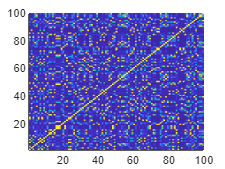


figure
pcolor(K)
shading flat

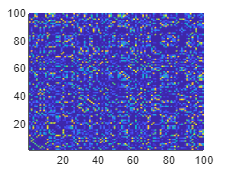

figure
pcolor(dK(:,:,1))
shading flat

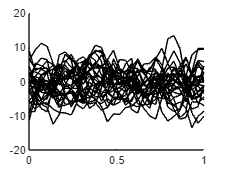

Z = GP([],d);
x1 = linspace(0,1,30)';

figure
hold on
for i = 1:30
    ysamp = Z.samplePrior(x1);
    plot(x1,ysamp,'LineWidth',0.05,'Color','k')
end

aa = normrnd(0*xx,0*xx+1);

tic
bb = K\aa

bb = 1.0e+04 *

    0.3461
    0.4061
    0.8182
   -0.1328
    0.1344
   -0.5387
   -1.0581
    0.6513
    1.0079
    0.5493


toc

Elapsed time is 0.025764 seconds.



d1 = d.addData(xx);

tic
cc = d1\aa

cgs stopped at iteration 100 without converging to the desired tolerance 1e-06
because the maximum number of iterations was reached.
The iterate returned (number 0) has relative residual 1.


cc =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


toc

Elapsed time is 4.389407 seconds.



sum(abs(bb-cc),'all')

ans = 5.7622e+05